# Application: Detecting cars

% URL of the (public) S3 bucket
bucketURL = "https://streamlit-self-driving.s3-us-west-2.amazonaws.com/";
% Save the XML locally
xmlFileName = "bucket_list.xml";
websave(xmlFileName, bucketURL);
% Read and parse the XML directly from the URL as a struct
S = readstruct(xmlFileName)

S = struct with fields:
    xmlnsAttribute: "http://s3.amazonaws.com/doc/2006-03-01/"
              Name: "streamlit-self-driving"
            Prefix: ""
            Marker: ""
           MaxKeys: 1000
       IsTruncated: "true"
          Contents: [1×1000 struct]


T = struct2table(S.Contents)

T = 1000×5 table
               Key                      LastModified                          ETag                   Size     StorageClass
    _________________________    __________________________    __________________________________    _____    ____________

    "1478019952686311006.jpg"    "2019-09-03T22:56:13.000Z"    "17593334a87be9a26a6caa1080d32137"    27406     "STANDARD" 
    "1478019953180167674.jpg"    "2019-09-04T00:28:39.000Z"    "9cfb405badb79f7781741f55d0ecc345"    26859     "STANDARD" 
    "1478019953689774621.jpg"    "2019-09-03T22:57:41.000Z"    "f2f2035d92c402a15ab1aaaaf971d733"    26442     "STANDARD" 
    "1478019954186238236.jpg"    "2019-09-03T23:04:32.000Z"    "3fe192a8ac3867e1ff0ef1fe9f34288d"    25669     "STANDARD" 
    "1478019954685370994.jpg"    "2019-09-03T23:01:42.000Z"    "514e4f5334

image = T.Key(48)

image = "1478019976185898081.jpg"

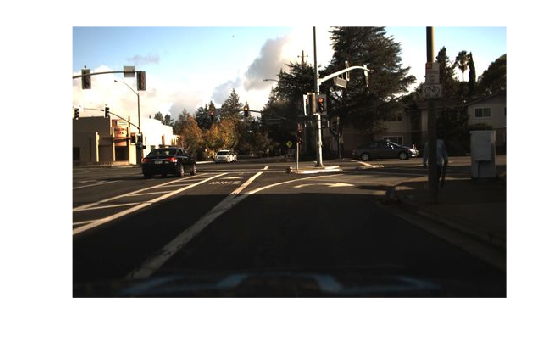

image_url = bucketURL+T.Key(48);
im = imread(image_url);
imshow(im)

websave(T.Key(48),bucketURL+T.Key(48));

### LLM-based detection

% prompt = "Detect if there is a car in the image.";
prompt = "Detect if there is a car in the image. Provide x_min, y_min, x_max, ymax coordinates as json";
response = chatVision(prompt, image_url)

response =     "{
       "car": {
         "x_min": 150,
         "y_min": 210,
         "x_max": 220,
         "y_max": 250
       }
     }"


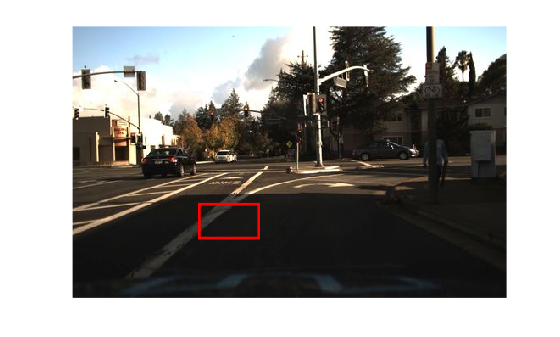

% Draw a bounding box around the car
coords = jsondecode(response).car;
imshow(im, 'Parent', axesHandle);
hold on; set(axesHandle, 'Color', 'none');
rectangle('Position', [coords.x_min, coords.y_min, coords.x_max - coords.x_min, coords.y_max - coords.y_min], 'EdgeColor', 'r', 'LineWidth', 2);
hold off

### Computer Vision

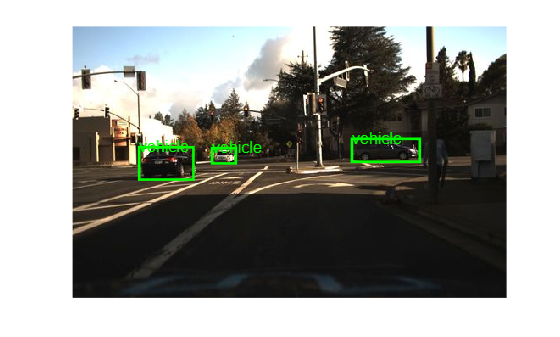

% Load the pre-trained vehicle detector (requires Automated Driving
% Toolbox)
detector = vehicleDetectorYOLOv2;

% Perform vehicle detection on the image
[bboxes, scores, labels] = detect(detector, im);

% Draw bounding boxes around detected vehicles
hold on;
imshow(im)
for i = 1:size(bboxes, 1)
    rectangle('Position', bboxes(i, :), 'EdgeColor', 'g', 'LineWidth', 2);
    text(bboxes(i, 1), bboxes(i, 2), string(labels(i)), 'Color', 'g', 'FontSize', 12);
end
hold off;

function response = chatVision(prompt, image, format)
    if nargin < 3
        format = "text"; % Set default format if not provided
    end
    chat = openAIChat(ModelName="gpt-4o-mini");
    messages = messageHistory;
    messages = addUserMessageWithImages(messages,prompt, image);
    response = generate(chat, messages,ResponseFormat=format);
end